## **Generate "Good" Variable**

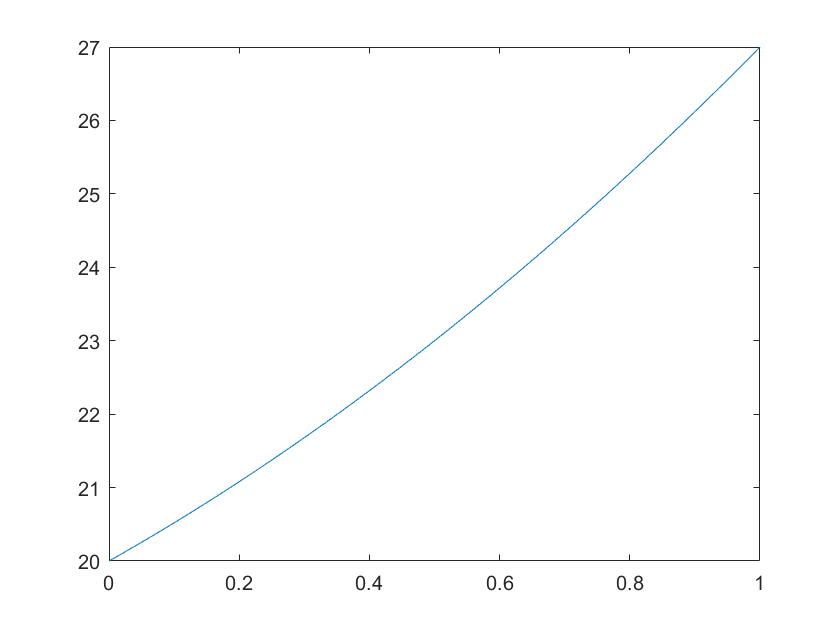

% fake equation:
% housing = 2x^2 + 5x + 20 
% where x is median income

% generate random x values within 10000-100000
income = 10000:1000:100000;
income = rescale(income);
y = 2*income.^2 +5*income + 20;
plot(income,y)

% peturb the y values as much by up to 10
perturbs =  rand(1,length(income)) + 1;
y = perturbs + y

y =    21.7348   21.0627   21.9057   21.5217   21.6896   21.7127   22.1055   22.2320   21.5779   22.2035   21.6767   22.3187   22.4419   21.9622   22.0564   22.7208   22.0140   22.6054   22.3001   22.4353   22.4005   23.0033   23.1713   22.8787   23.2330   22.9797   23.1456   23.0797   23.0795   23.6976   23.1976   23.0675   23.1318   24.0991   23.1866   23.5998   23.3381   23.4706   23.6509   23.5796   23.6803   24.3731   24.3670   24.6711   24.7973   24.1783   24.6015   24.2600   24.7268   25.0569


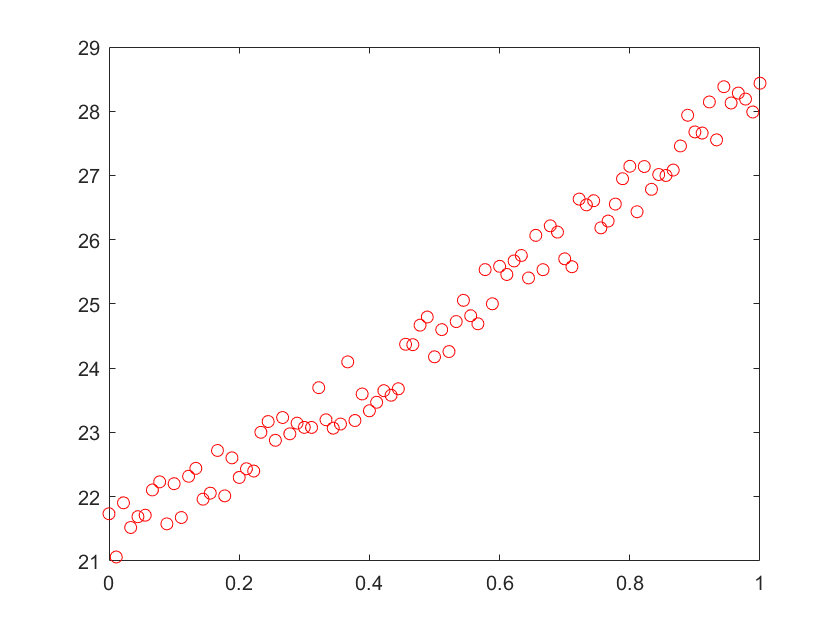

plot(income,y, 'ro')

## **Generate Other Variables**

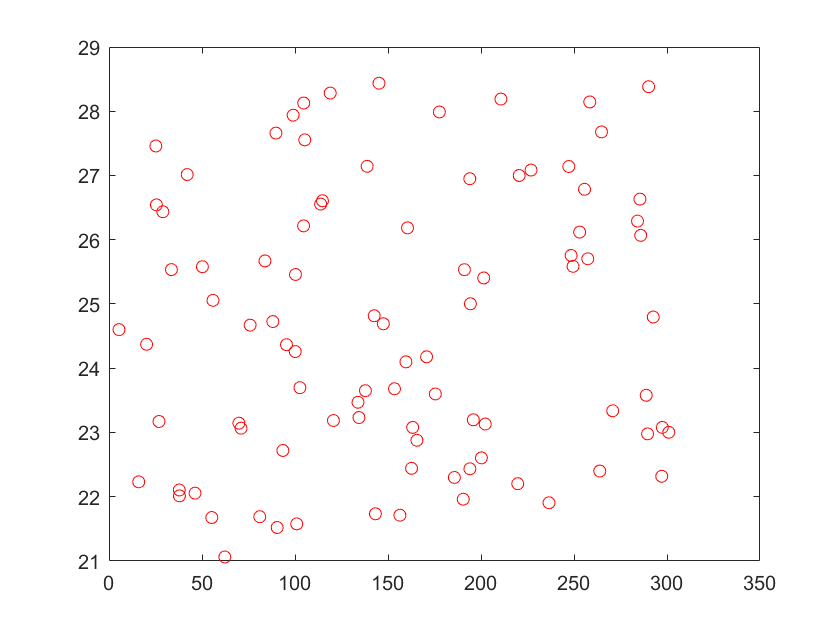

% fake other variable, such as total bedrooms
% range from 1-300
% have to match the data set
totalBedrooms = zeros(1,length(y));
for i=1:length(y)
    bedroomCount = 300*rand + 1;
    totalBedrooms(i) = bedroomCount;
end

plot(totalBedrooms,y, 'ro')

## **Save Variables For Future Use**

% create a table
income = income';
totalBedrooms = totalBedrooms';
y = y';
housingData = table(income,totalBedrooms,y);
save('housingData', 'housingData');